# Determine whether a Function Satisfies the Wave Equation using MATLAB

*Brendan McCracken, PE*

## Problem definition

A given reference manual of unknown origin, concerning the vibration of strings, states that a particular function satisfies the wave equation. The function, $s\left(x,t\right)$, follows:

clear
syms x t real % space, time
syms c positive % wave speed, assumed to be positive
s = cos(x+c*t)/2 + cos(x-c*t)/2

$$s = \frac{\cos\left(x+c\,t\right)}{2}+\frac{\cos\left(x-c\,t\right)}{2}$$

We might recall from d'Alembert that the superposition of a left traveling wave and right traveling wave with the same wave speed, $c$, should be a solution to the wave equation. Let's verify this result to certify that the source is accurate and document the derivation in a Live Script to share with other MATLAB users or export a .pdf report for archival purposes.

Solutions to separable equations, such as the wave equation, are often written in the form: $s\left(x,t\right)=X\left(x\right)\cdot T\left(t\right)$. Being able to re-write the function in these terms using the Simplify Live Editor Task will make the function easier to work with and gives a positive indication.

% Compute simplified symbolic expression
u = simplify(s)

$$u = \cos\left(c\,t\right)\,\cos\left(x\right)$$

## Show that `u(x,t)` satisfies the wave equation

The one dimensional wave equation is given as follows:


$$$\frac{\partial^2 }{\partial t^2 }u=c^2 \frac{\partial^2 }{\partial x^2 }u$
$$


The left-hand side, substituting u:

lhs=diff(u,t,2)

$$lhs = -c^{2}\,\cos\left(c\,t\right)\,\cos\left(x\right)$$

The right-hand side, substituting u:

rhs=c^2*diff(u,x,x)

$$rhs = -c^{2}\,\cos\left(c\,t\right)\,\cos\left(x\right)$$

Does LHS=RHS given the assumptions? If so, s satisfies the wave equation.

isAlways(lhs==rhs)

ans = logical
   1

## Plot the solution for a given wave speed

Select a numeric value for c and call it cn.

cn=0.8

cn = 0.8000

Convert u to a MATLAB function for further plotting and numeric analysis

f=matlabFunction(subs(u,c,cn))

f = function_handle with value:
    @(t,x)cos(t.*(4.0./5.0)).*cos(x)

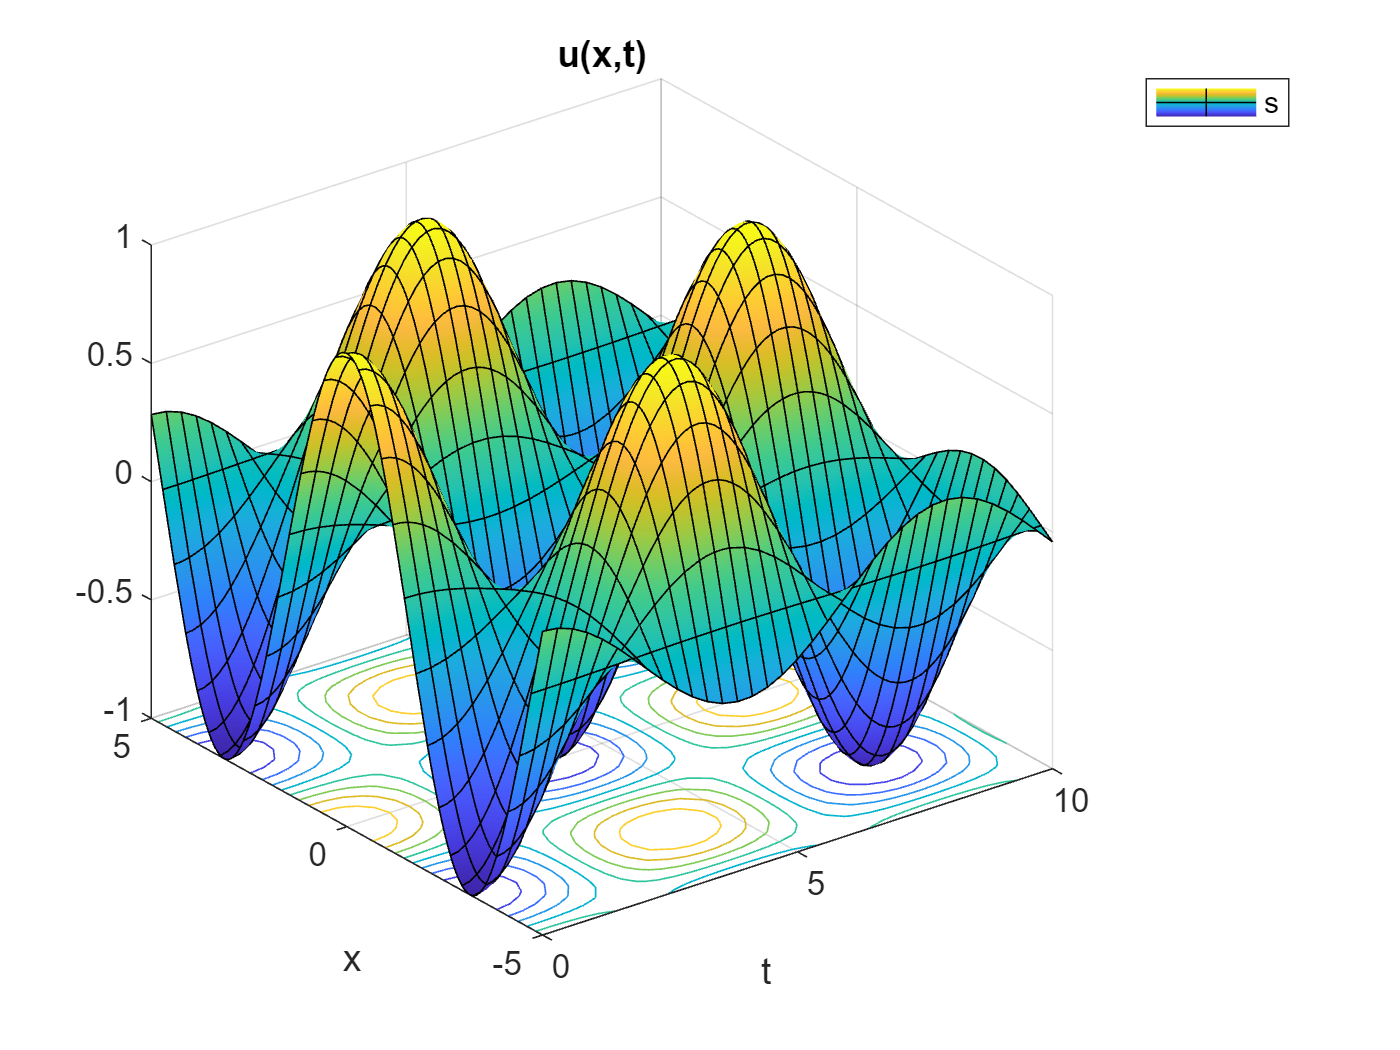

interval=[0 10 -5 5];
% Create fsurf of f and interval
fs = fsurf(f,interval,"ShowContours","on","DisplayName","f");

% Add xlabel, ylabel, title, and legend
legend("s")
xlabel("t")
ylabel("x")
title("u(x,t)")